１：RFデータに対してフーリエ変換処理をかける．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter\case1')
load('rfdata')
load('sourse_wave')
load('param')
load('kgrid')

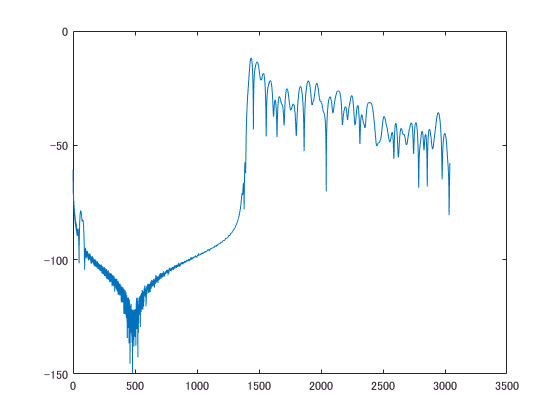

figure;
plot(20*log10(abs(hilbert(rfdata(:,150,50)))));

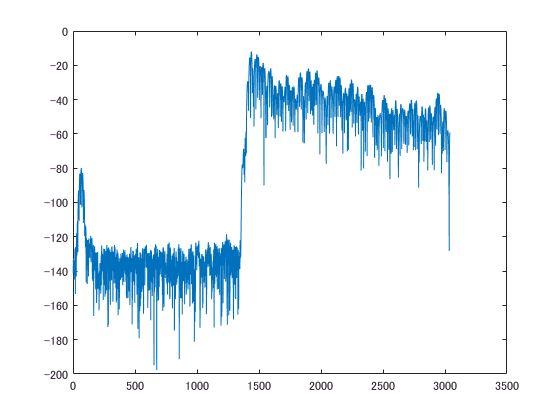

figure;
plot(20*log10(abs(rfdata(:,150,50))));

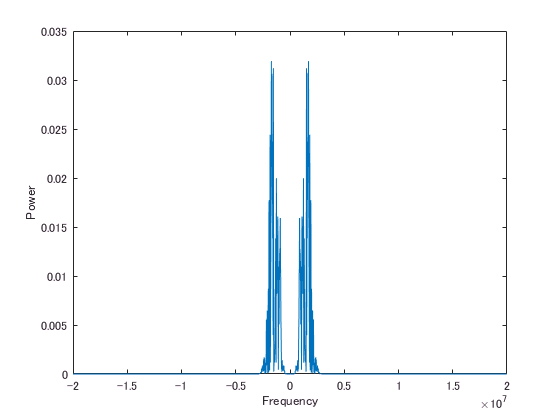

fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(rfdata(:,150,50));
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure;
plot(f0,power0)
xlabel('Frequency')
ylabel('Power')

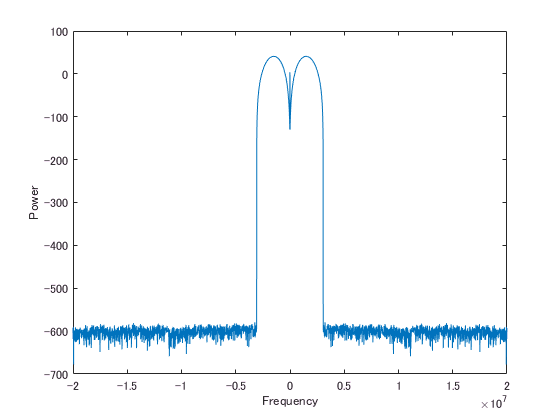

fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(source_wave);
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

figure;
plot(f0,20*log10(power0))
xlabel('Frequency')
ylabel('Power')

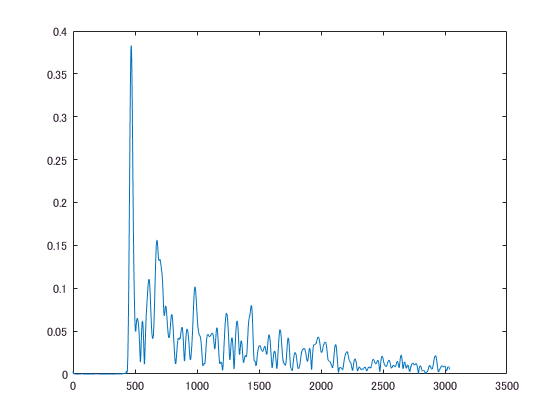

figure;
plot(abs(hilbert(rfdata(:,50,80))));

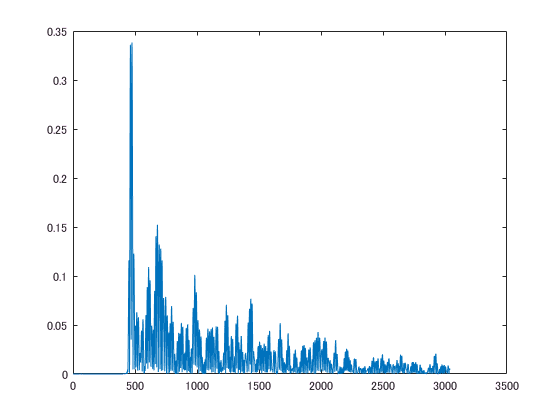

% findpeaks(abs(hilbert(rfdata(:,50,80))))
figure;
plot(abs(rfdata(:,50,80)));

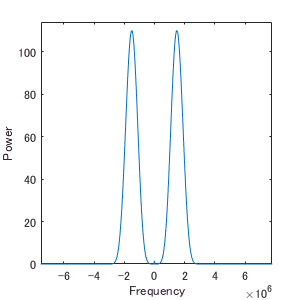

figure;
fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(source_wave);
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0_2 = abs(y0).^2/n;    % 0-centered power

plot(f0,(power0_2))
xlabel('Frequency')
ylabel('Power')

xlim([-7511521 7788018])
ylim([0 114])
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_21_FFT_RealisticModel\Pwspctr_sourcewave','png',[300,300]);

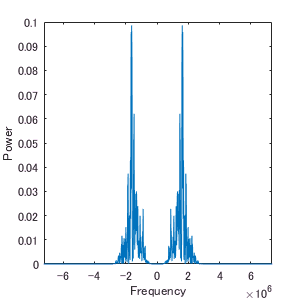

figure;
fs = param.sensor.freq;
t = kgrid.t_array;
y = fft(rfdata(:,50,80));
n = length(t);


y0 = fftshift(y);         % shift y values
f0 = (-n/2:n/2-1)*(fs/n); % 0-centered frequency range
power0 = abs(y0).^2/n;    % 0-centered power

plot(f0,(power0))
xlabel('Frequency')
ylabel('Power')
xlim([-7222222 7342259])
ylim([0.000 0.100])
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_21_FFT_RealisticModel\Pwspctr_rfdata','png',[300,300]);

最大値の平均(nearest-path) vs EMCL率 (n=25)

avemax_rf = zeros(1,25);
max_rf2 = zeros(1,100);
for i = 1:25
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
    myfilename = sprintf('case%d',i);
    cd(myfilename)
    load('rfdata')
    max_rf = max(rfdata,[],1);
    max_rf = max_rf(1,101:200,:);
    max_rf = reshape(max_rf,100,100);
    for j = 1:100
        max_rf2(1,j) = max_rf(j,j);
    end
    avemax_rf(1,i) = mean(max_rf2);
end
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_21_FFT_RealisticModel')
save('avemax_rf.mat', 'avemax_rf');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
save('avemax_rf.mat', 'avemax_rf');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
load('rate_EMCLs');

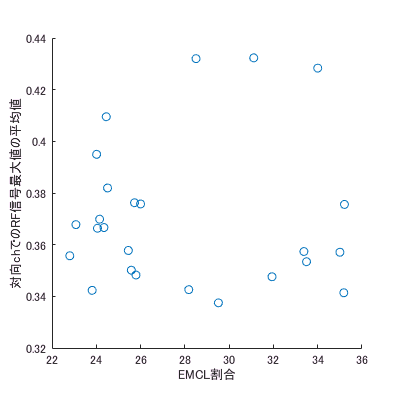

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter')
load('rate_EMCLs');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_08_12_realisticScatter')
load('avemax_rf')
figure;
scatter(rate_EMCLs(1,:),avemax_rf(1,:));
xlabel('EMCL割合');
ylabel('対向chでのRF信号最大値の平均値')
axis square
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_21_FFT_RealisticModel\avemax_vs_EMCL','png',[400,400]);